syms s t

g = 2*sin(3*t)*cos(5*t)

$$g = 2\,\cos\left(5\,t\right)\,\sin\left(3\,t\right)$$

Wo = k_avg/s^2+s

$$Wo = \frac{1}{s^{2}}$$

[WoNum, WoDen] = numden(Wo)

$$WoNum = 1$$

$$WoDen = s^{2}$$

[WgNum, WgDen] = numden(laplace(g))

$$WgNum = 6\,s^{2}-96$$

$$WgDen = \left(s^{2}+4\right)\,\left(s^{2}+64\right)$$

syms c c0
WrDen = c * WgDen * (s+c0)

$$WrDen = c\,\left(s^{2}+4\right)\,\left(s^{2}+64\right)\,\left(c_{0}+s\right)$$

syms c1 c2 c3 c4 c5 c6
WrNum = c1*s^5 + c2*s^4 + c3*s^3 + c4*s^2 + c5*s + c6

$$WrNum = c_{1}\,s^{5}+c_{2}\,s^{4}+c_{3}\,s^{3}+c_{4}\,s^{2}+c_{5}\,s+c_{6}$$

pol = coeffs(WrNum*WoNum+ WrDen*WoDen, s, 'All')

$$pol = \left(\begin{array}{cccccccc} c & c\,c_{0} & 68\,c+c_{1} & c_{2}+68\,c\,c_{0} & 256\,c+c_{3} & c_{4}+256\,c\,c_{0} & c_{5} & c_{6} \end{array}\right)$$

polaa = WrNum*WoNum+ WrDen*WoDen

$$polaa = c_{6}+c_{5}\,s+c_{1}\,s^{5}+c_{2}\,s^{4}+c_{3}\,s^{3}+c_{4}\,s^{2}+c\,s^{2}\,\left(s^{2}+4\right)\,\left(s^{2}+64\right)\,\left(c_{0}+s\right)$$

neededPol = coeffs((s+1)*(s+1)*(s+1)*(s+1)*(s+1)*(s+1)*(s+1), s, 'All')

$$neededPol = \left(\begin{array}{cccccccc} 1 & 7 & 21 & 35 & 35 & 21 & 7 & 1 \end{array}\right)$$

sol = solve(pol == neededPol)

sol = struct with fields:
     c: 1
    c0: 7
    c1: -47
    c2: -441
    c3: -221
    c4: -1771
    c5: 7
    c6: 1



WrNumSol = sym2poly(subs(WrNum, [c c0 c1 c2 c3 c4 c5 c6], [sol.c sol.c0 sol.c1 sol.c2 sol.c3 sol.c4 sol.c5 sol.c6]))

WrNumSol =          -47        -441        -221       -1771           7           1


WrDenSol = sym2poly(subs(WrDen, [c c0], [sol.c sol.c0]))

WrDenSol =            1           7          68         476         256        1792



simtime = 40

simtime = 40


first = sim("Task6.slx", simtime)

first =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                      g: [1x1 timeseries] 
                   tout: [40001x1 double] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


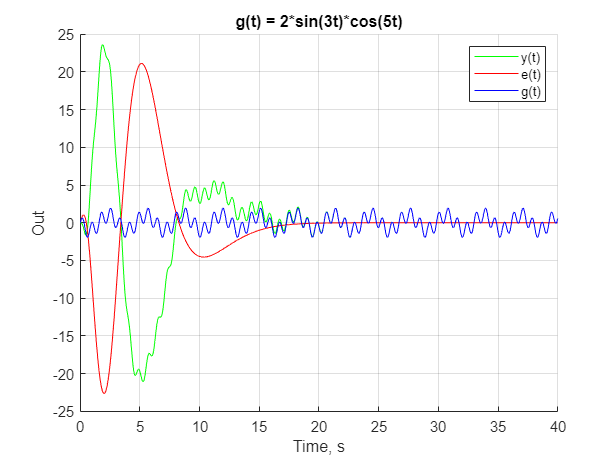

hold on
plot(first.y.Time, first.y.Data, 'green')
plot(first.e.Time, first.e.Data, 'red')
plot(first.g.Time, first.g.Data, 'blue')

xlabel("Time, s")
ylabel("Out")
grid on
title('g(t) = 2*sin(3t)*cos(5t)')
legend("y(t)", "e(t)", "g(t)")